# Manual para implementar DMD a estructuras de flujo

## Juan Sebastián Hincapié

## Pre-procesamiento: matriz de Snapshots

Antes de empezar con la programación pura y dura de la descomposición modal, es esencial que el programador responda a la pregunta ¿Qué propiedad del fluido o del fenómeno se desea descomponer en modos? Ya que se puede descomponer una gran variedad de propiedades tales como  la temperatura, la presión, las componenetes de la velocidad, la viscosidad del fluido, vorticidad, etc. 

Teniendo claro con qué propiedad se va a trabajar, se procede a organizar los datos obtenidos de la simulación CFD. El campo de dicha propiedad a lo largo del tiempo se organiza en tantas matrices $\mathbf x(r, t_k)$ como paso temporales se quieran incluir en la descomposición modal. Por lo tanto, cada matriz agrupa el campo de la propiedad en un paso temporal $t_k
$específico de la simulación. Además, al interior de la matriz $\mathbf x(r, t_k)$ el valor nodal de la propiedad se ordena según la posición del nodo al que corresponde, donde $r_{i,j}$ representa la vorticidad en el nodo $(i,j)$.


$$\mathbf{x}\left(\mathbf{r}, t_k\right)=\left[\begin{array}{cccc}
x\left(r_{1,1}, t_k\right) & x\left(r_{1,2}, t_k\right) & \cdots & x\left(r_{1, p}, t_k\right) \\
x\left(r_{2,1}, t_k\right) & x\left(r_{2,2}, t_k\right) & \cdots & x\left(r_{2, p}, t_k\right) \\
\vdots & \vdots & \ddots & \vdots \\
x\left(r_{q, 1}, t_k\right) & x\left(r_{q, 2}, t_k\right) & \cdots & x\left(r_{q, p}, t_k\right)
\end{array}\right]$$


Cada una de las matrices $\mathbf x(r, t_k)$ se transforma en un vector "alto" y "delgado" de la siguiente manera:


$$\mathbf{x}_k=\left[\begin{array}{c}
x\left(r_{1,1}, t_k\right) \\
x\left(r_{1,2}, t_k\right) \\
\vdots \\
x\left(r_{2,1}, t_k\right) \\
\vdots \\
x\left(r_{q, p}, t_k\right)
\end{array}\right] $$


Esta transformación se puede llevar a cabo usando el comando **reshape **de Matlab. Por ejemplo:

Data = [1 2 3;
        4 5 6;
        7 8 9];

i = 1; %Número de columnas
j = 9; %Número de filas
disp('Matriz Data con la nueva forma alta y delgada:')

Matriz Data con la nueva forma alta y delgada:


snap = reshape(Data, j, i)

snap =      1
     4
     7
     2
     5
     8
     3
     6
     9


Cada uno de los vectores $\mathbf x_k$ se agrupa en lo que se conoce como la matriz de **snapshots** $\mathbf X$:


$$\mathbf{X}=\left[\begin{array}{cccc}
\mid & \mid & & \mid \\
\mathbf{x}_1 & \mathbf{x}_2 & \cdots & \mathbf{x}_m \\
\mid & \mid & & \mid
\end{array}\right]$$


El libro Dynamic Mode Decomposition publicado por J. Nathan Kutz, Steven L. Brunton, Bingini W. Brunton y Joshua L. Proctor brinda el campo de velocidad, vorticidad y de presión para la simulación del flujo alrededor de un cilindro con Reynold 100. Estos datos ya están agrupados en matrices snapshots, así que no es necesario hacer el procedimiento antes mencionado. Los detalles de la simulación se pueden encontrar en el capítulo 2 del libro. 

Se debe descargar el archivo **DATA.zip **desde la página [http://dmdbook.com/.](http://dmdbook.com) Al descomprimirla se generan una serie de carpetas. Dentro de la carpeta llamada **Fluids** se encuentran archivos de extensión **.mat**. Para este estudio, únicamente se trabjará con **CYLINDER_ALL.mat**. Se puede hacer una copia de este archivo en una carpeta aparte.

Empezamos extrayendo la información del campo de vorticidad del archivo **CYLINDER_ALL.mat**. Esta información se puede llamar con el nombre de la llave, que para este caso es "VORTALL".  Es buena prática trabajar/programar con la copia de los datos y no con la fuente misma.

load("CYLINDER_ALL.mat", "VORTALL")
Avort = VORTALL(:,1:150);

## Factorización SVD

Luego se usa el método SVD (Singular Value Decomposition, por sus siglas en inglés) que se encarga de factorizar la matriz de snapshots **Avort** de dimensiones 89351x150 en tres matrices:

- **U: **matriz ortonormal. Cuando se usar Full SVD tiene dimensiones 89351x89351; pero cuando se usa Reduced SVD tiene dimensiones 89351x150.

- $\Sigma$**: **matriz de valores singular. Para Full SVD tiene dimensiones 89351x150; pero cuando se usar Reduced SVD tiene dimensiones 150x150.

- **V: **matriz ortonormal. Esta matriz es de dimensión 150x150 tanto en Full como en Reduced SVD.

La factorización es de la sigueintes forma:


$$\mathbf{A} = \mathbf{U}\Sigma\mathbf{V^T}$$


**Nota:** ¿Hay alguna ventaja en usar un método u otro? Sí y enorme, en términos de memoria computacional requerida para el cáculo de SVD, pues el método Reduced usa matrices de menor tamañao que en el método Full. Por otro lado, se puede llegar a pensar que que el método RSVD es menos preciso que FSVD, dado que usa menos información; pero no es así. Ambos están al mismo nivel de precisión. Un ejemplo a continuación para ilustrar los anterior:

%Ejemplo
disp('La matriz a factorizar es:')

La matriz a factorizar es:


A = [3,1;1,2;6,5]

A =      3     1
     1     2
     6     5


disp('Factorización completa:')

Factorización completa:


[U, S, V] = svd(A)

U =    -0.3454    0.7514   -0.5623
   -0.2360   -0.6494   -0.7229
   -0.9083   -0.1170    0.4016


S =     8.5967         0
         0    1.4482
         0         0


V =    -0.7819    0.6234
   -0.6234   -0.7819


disp('Factorización reducida. Notar la diferencia de tamaño entre U y S')

Factorización reducida. Notar la diferencia de tamaño entre U y S


[U, S, V] = svd(A, "econ")

U =    -0.3454    0.7514
   -0.2360   -0.6494
   -0.9083   -0.1170


S =     8.5967         0
         0    1.4482


V =    -0.7819    0.6234
   -0.6234   -0.7819


Continuando con el procedimiento, aplicamos la factorización **SVD** a la matriz *Avort* utilizando el comando *svd* con la opción *'econ'* para calcular la factorizar con la forma reducida. Además, se calcula el productor entre las matrices *S* y *V*:

[U, S, V] = svd(Avort, "econ");
alpha = S*V';

Esta es la base para del método que sigue a continuación: el POD (Descomposición Ortogonal Adecuada, por sus siglas en inglés). Este método numérico permite "descomponer" el flujo en estructuras coeherentes o modos a partir de los datos de simulación.  Lo que se debe hace es truncar la factorización SVD, es decir, usar unos cuantos valores singulares, no todos,  para representar el flujo en un tiempo específico:

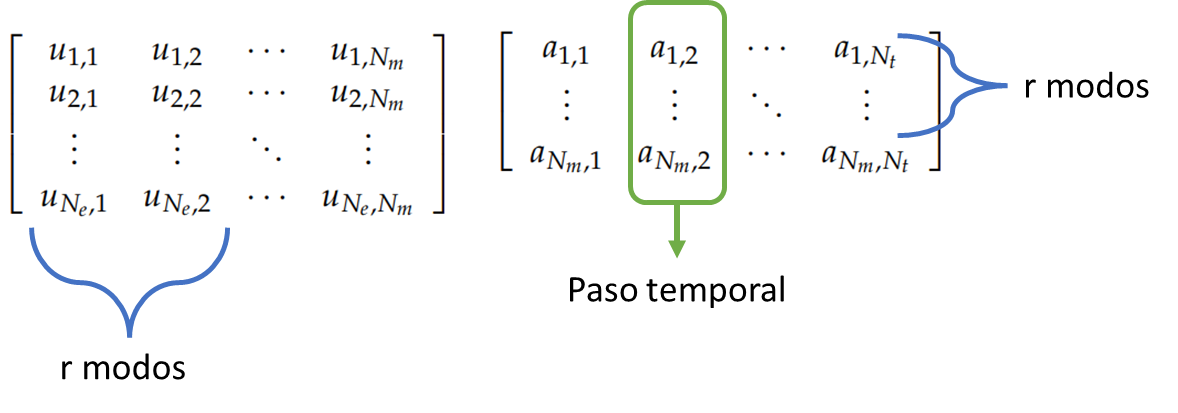

La primera matriz es *U* y la segunda matriz, llamada matriz de coeficientes, es *alpha* o el producto entre *S* y *V*. El número de columnas de *U* es igual al número de modos que tiene el sistema, y el número de filas es igual al número de valores nodales. Por otro lado, en *alpha*, el número de columnas es igual al número de pasos temporales y el número filas es igual al número de modos que tiene el sistema. Por tanto, para representar el flujo con **r** modos, se debe selecionar **r columnas** de *U* y **r filas **de *alpha*. Adicionalmente, se seleciona la columna de *alpha* que representa el paso temporal deseado. 

## Contenidos energético

En este punto puede surgir naturalmente una pregunta ¿Cuántos modos utililizar para la representación de la estructura? o coloquilamente ¿Cuál sería el número mágico de modos? Y la respuesta es simple: depende de la aplicación. Sí, depende de qué tanta información se puede perder, y eso lo define la aplicación. Para tener más cirterios de selección se puede hacer dos gráficas complementarias entre sí:

-  La primera representa la energía (o información) contenida en cada uno de los modos del sistema. El valor de *n* representa el número de modos totales


$$E_i = \frac{\sigma_i}{ \sum_{i=1}^{n} \sigma_i}$$


- La segunda grafica representa la energía acumualda a medida que se añaden más modos. El valor de *r* representa el número de modos usado en el truncamiento del SVD::


$$E_i = \frac{\sum_{i=1}^{r} \sigma_i}{ \sum_{i=1}^{n} \sigma_i}$$


A continuación se presenta le código empleado para construir las dos gráficas. Se usaron 20 modos en el truncamiento.

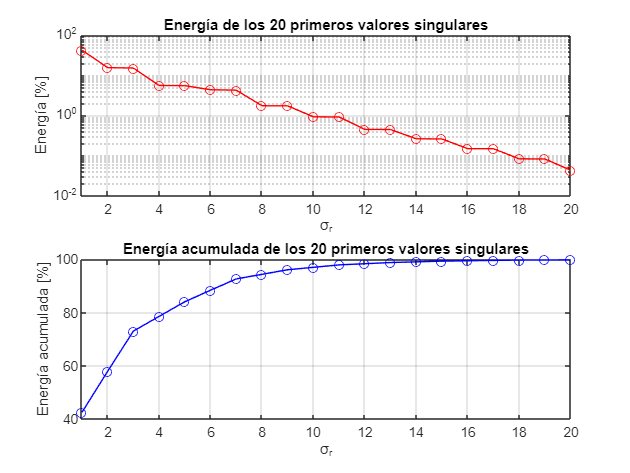

sDiagonal = diag(S);           %Construyo un vector con la diagonal de S
sSuma = sum(sDiagonal);        %Sumo el vector y guardo el valor
sSumatoria = cumsum(sDiagonal);%Suma acumulativa

singularEnerg = sDiagonal/sSuma *100;       %Energía de cada modo en porcentaje
singularEnergAcum = sSumatoria/sSuma *100;  %Energía en porcentaje
r = 20;                                     %Número de valores singulares a usar 

fig = 0;
figure(fig+1);
subplot(2,1,1)
semilogy(singularEnerg(1:r), "-or")
title(sprintf("Energía de los %d primeros valores singulares",r))
xlabel("\sigma_r")
ylabel("Energía [%]")
xlim([1 r])
grid on

subplot(2,1,2)
plot(singularEnergAcum(1:r), "-ob")
title(sprintf("Energía acumulada de los %d primeros valores singulares",r))
xlabel("\sigma_r")
ylabel("Energía acumulada [%]")
xlim([1 r])
grid on
hold off

Podemos observar de la primera gráfica que el contenido energético de los modos va decreciendo; esto se debe a que en el método numérico SVD, los valores singulares están ordenados de mayor a menor en la matriz *S*. A medida que vamos utilizando más modos, mayor información del sistema estaremos representando en la reconstrucción del flujo, como se puede ver en la gráfica de energía acumulada. Con esta información, se puede escoger el número de modos apropaidos para representar con fidelidad la estructura; pero sin hacer muy pesado computacionalmente la reconstrucción.

## Modos estables

Otro pregunta que hay que responderse, y que no suele surgir naturalmente, antes de ejecutar el POD es ¿Qué modos del sistemas son estables? Esta pregunta es imporatan responderla porque, básicamente los modos estables son los que deberían usarse para la reconstrucción del flujo y aquellos que son inestables no deben ni "mirarse" porque arruinan la reconstrucción. 

Y bien ¿Cómo saber qué modos son estables? Primero se debe definir la martiz $\mathbf{A}^\sim$:


$$\mathbf{A}^\sim \approx \mathbf{U}\mathbf{X}^T \mathbf{V}\mathbf{\Sigma^{-1}}$$


Donde $\mathbf{X}$ es la matriz de Snapshots. Luego se calculan los autovalores de la matriz $\mathbf{A}^\sim$ y se grafican en el plano complejo. Si los autovalores se encuentran sobre o dentro de la circunferencia del círculo unitario, significa entonces que son estables y por tanto que pueden ser usados para la resconstrucción del flujo. Los modos que estén por fuerza del circulo unitario son inestables.

Avortex1 = VORTALL(:,1:end-1);
Avortex2 = VORTALL(:,2:end);

r = 21;
U = U(:, 1:r);
S = S(1:r,1:r);
V = V(:, 1:r);
Awierd = U'*Avortex2*V*inv(S);

[W,eigs] = eig(Awierd);
Phi = Avortex2*V*inv(S)*W;
hold off

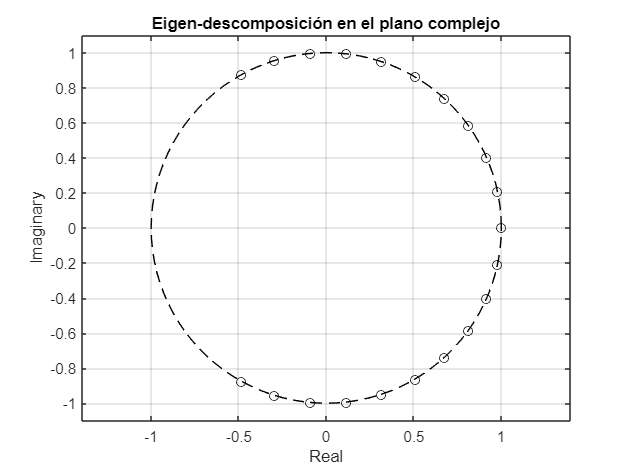

fig = fig+3;
figure(fig)
theta = (0:1:100) *2*pi/100;
plot(cos(theta),sin(theta),"k--") % plot unit circle
hold on, grid on
scatter(real (diag (eigs)),imag (diag(eigs)),"ok")
axis ([-1.1 1.1 -1.1 1.1]);
axis equal;
title("Eigen-descomposición en el plano complejo")
xlabel("Real")
ylabel("Imaginary")
hold off

## Reconstrucción del sistema

Primero echémosle un vistazo al sistema original. En libro de donde se sacaron los tomas indican que la matriz de Snapshot se organizó con tomando datos de la simulación cada $10\Delta t$, donde el $\Delta t = 0.02$ para satsifacer número de CFL. Además, usaron un dominio espacial con 449 nodos en dirección X y 199 nodos en dirección Y.  

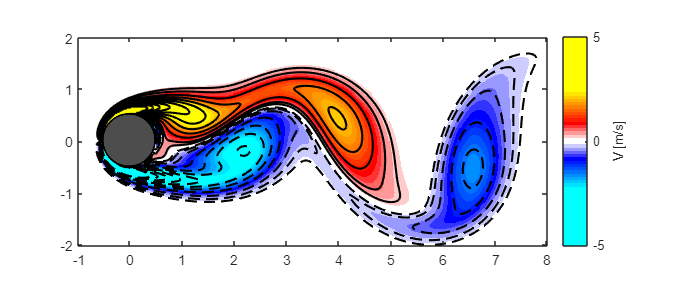

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


delta_t = 0.02;                     %Paso temporal
t_analisis = 15;                    %Tiempo que se desea graficar
t_index = t_analisis/(10*delta_t);  %índice dentro de la matriz de Snapshots

nx = 199;
ny = 449;
prueba1 = reshape(Avort(:,t_index),nx,ny);

fig = fig +1;
figure(fig);
plotVortex(prueba1)

Con esta figura se puede visualizar el fenómeno de la **calle de vórtices de Von Kármán**,  patrón de vórtices que se repite debido a la separación no estacionaria de la capa de fluido al pasar sobre cuerpos sumergidos, en este caso, de un cilindro de longitud infinita.

Ahora bien, conociendo el contenido energético de los modos y habiendo identificado cuáles son estables, ya se puede pasar a la reconstrucción del sistema. Si aún no se tiene claro cuántos modos usar, se podrían hacer varios experimentos y validar por inspección visual qué tan bien se está reconstruyendo el flujo. Grafiquemos los primeros 8 modos por separado:

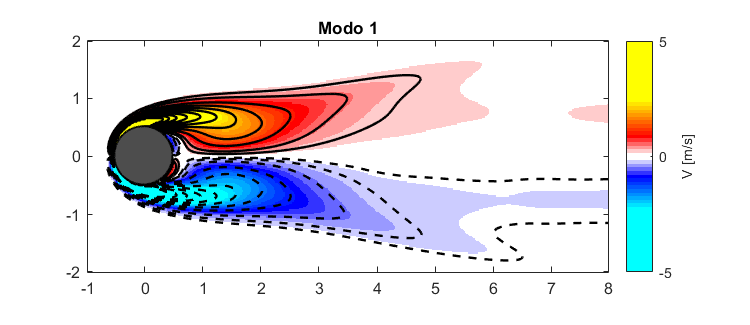

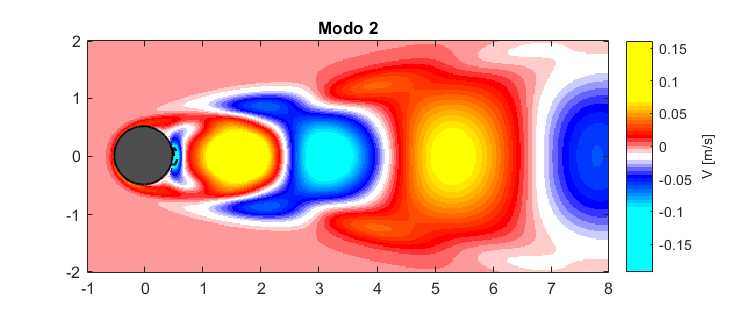

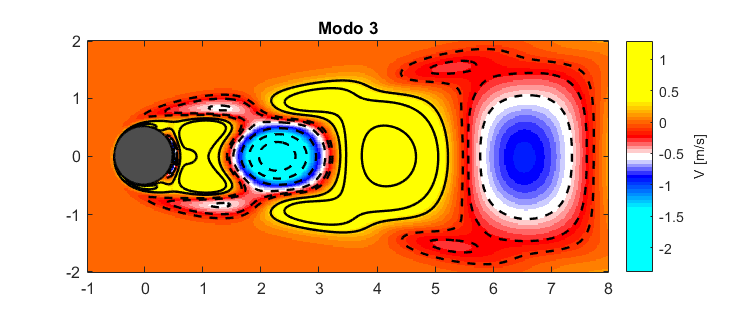

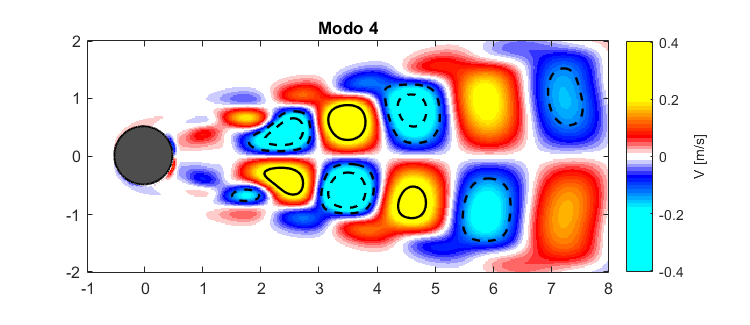

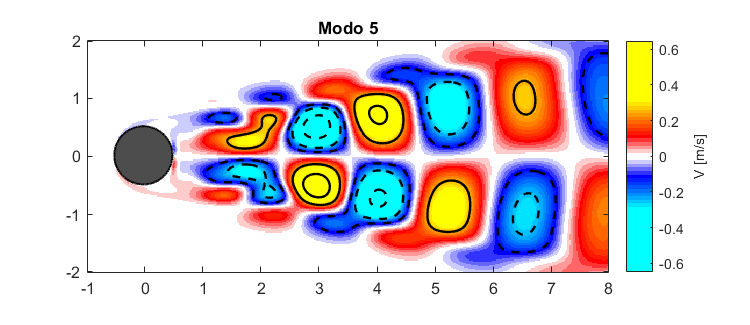

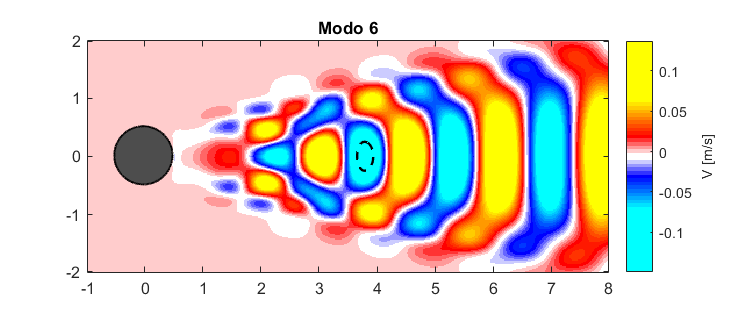

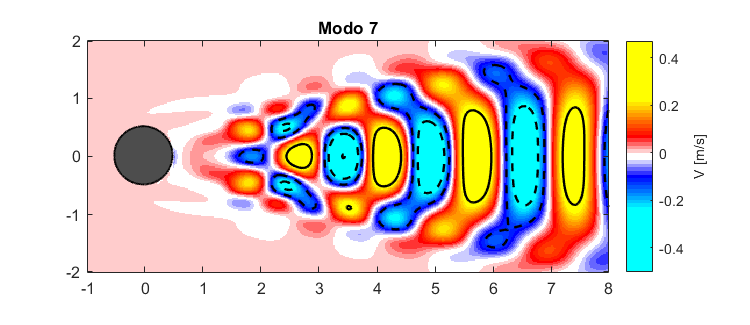

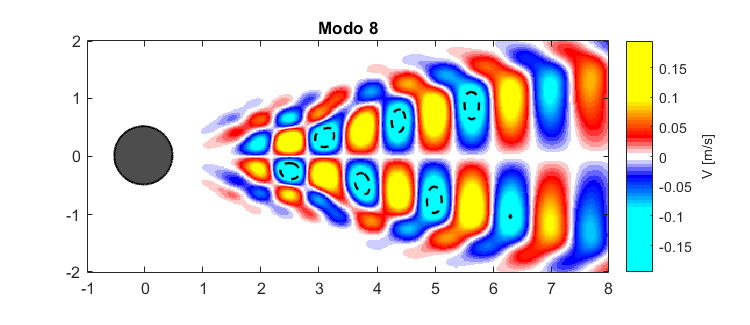

%Estudiamos los modos por separado
r = [1:1:8];
modes(r, U, alpha, t_index, nx, ny)

¿Qué representa cada uno de estos modos?

- El modo 1 contiene las características principales de flujo, sin el componente oscilatorio.

- El modo 2 representa el desprendimiento de vórtices. Crece asintóticamente.

- Modo 2 y 3 son complementarios y representan el desprendimiento de los vórtices. Contienen oscilación en el eje horizontal.

- Modo 4 y 5 son complementarios y representan el desprendimiento y la oscilación en el eje vertical y horizontal.

A modo de ejemplo, usamos los 5 primeros modos para reconstruir el sistemas:

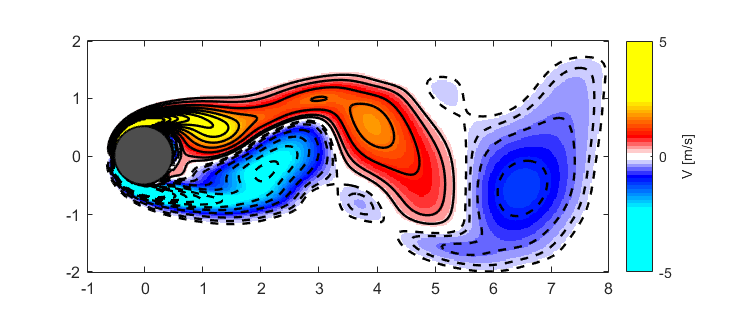

ans =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


r = 5;
%Contruyo mis matrices usando r modos
U_red = U(:, 1:r);
alpha_red = alpha(1:r,:);

Avort_red = U_red*alpha_red(:,t_index);
Avort_red5 = reshape(Avort_red,nx,ny);
fig = fig+1;
figure(fig);
plotVortex(reshape(Avort_red,nx,ny))

Ahora reconstruyamos el sistema usando 8 modos:

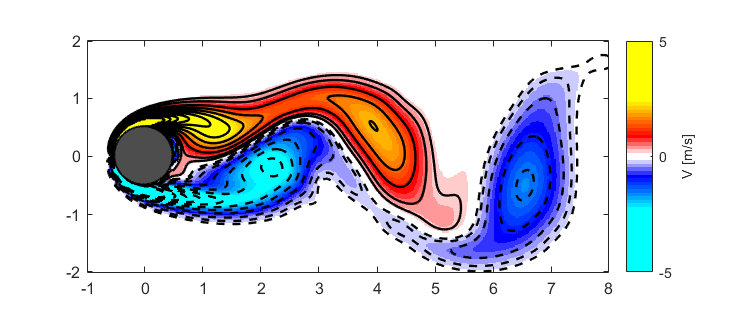

ans =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


r = 8;
%Contruyo mis matrices usando r modos
U_red = U(:, 1:r);
alpha_red = alpha(1:r,:);

Avort_red = U_red*alpha_red(:,t_index);
Avort_red8 = reshape(Avort_red,nx,ny);
fig = fig+1;
figure(fig);
plotVortex(reshape(Avort_red,nx,ny))

## Cuantificar pérdida de información

A medida que vamos añadiendo modos en la combinación lineal, mejor es la aproximación. Esto se pudo comprobar por medio de una inspección visual, revisando simplemente los "detalles" de la gráfica. Sin embargo, en ciencia es importante cuantificar el error.Esto se puede hacer por medio de la siguiente ecuación:


$$\left( \sum_{j=1}^{cols} \sum_{i=1}^{rows} |\mathbf{a_{ij}} -\mathbf{a_{ij}}^{\sim} |^2 \right)^{(1/2)}$$


%Error entre la matriz orginal y la matriz con 5 modos
error5 = norm(prueba1-Avort_red5, "fro")/norm(prueba1, "fro")*100

error5 = 13.3776

%Error entre la matriz orginal y la matriz con 8 modos
error8 = norm(prueba1-Avort_red8, "fro")/norm(prueba1, "fro")*100

error8 = 4.2784

El error calculado por medio de la norma $L_2$ disminuye a medida que aumenta el número de modos.

## Modo Dinámico de Descomposición 

El modo dinámico de descomposición, también conocido como DMD por sus siglas en inglés, es una nueva técnica bastante poderosa para descubrir la dinámico de sistemas a partir de datos de alta dimensión. La popularidad del DMD se debe a que es un método que no requiere ecuaciones, pues se basa en datos, y es capaz de descomponer un sistema complejo en estructuras espacio-temporales coherentes, que posterioremente se peuden utilizar para predecir e incluso implementar técnicas de control a corto plazo.

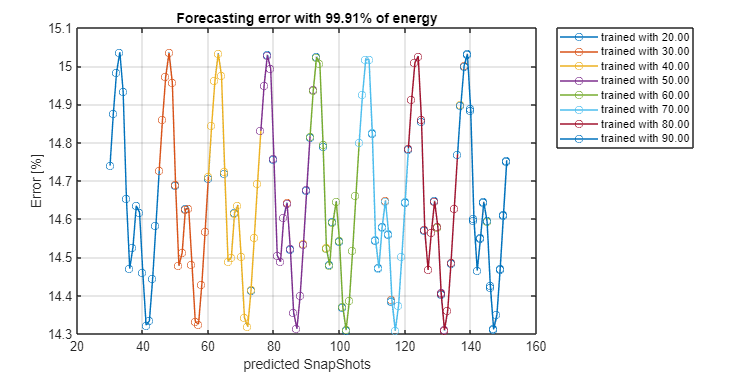

%Cargo los archivos
load("CYLINDER_ALL.mat", "VORTALL");
XComplete = VORTALL(:,1:end);
[Uc, Sc, Vc] = svd(XComplete, "econ");

%Time configuration CFD simulation
total = size(XComplete, 2);
dt = 0.02*10;
tInital = dt;
tFinal = (total)*dt;
time = tInital:dt:tFinal;

%Time configuration for training
trainingPercent = 0.2:0.1:0.9;
reqEnergy = 99.9; %In percentage
fig = fig+1;
[Phi,omega,lambda, reqModes, errorSnap, energy] = errorCycle(trainingPercent, reqEnergy, XComplete, dt, time, fig);

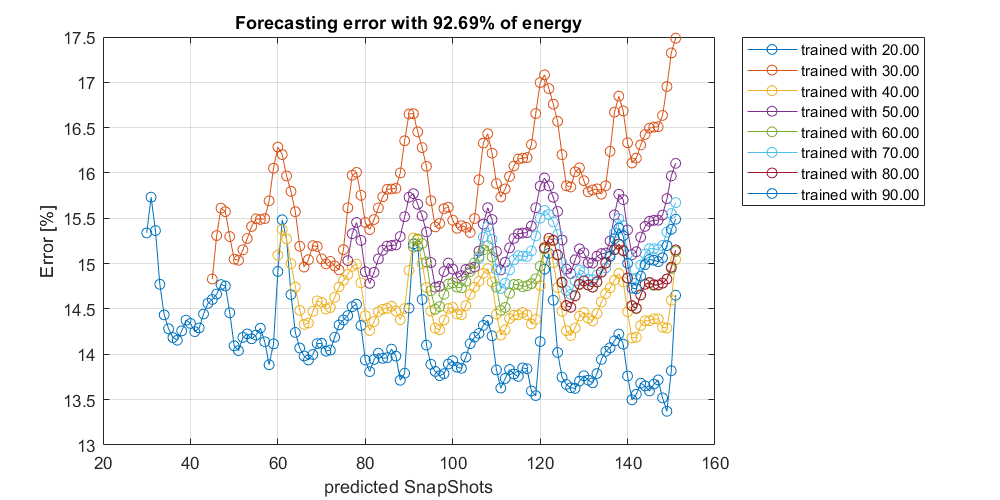

reqEnergy1 = 92.00; %In percentage
fig = fig+1;
[Phi1,omega1,lambda1, reqModes1, errorSnap1, energy1] = errorCycle(trainingPercent, reqEnergy1, XComplete, dt, time, fig);

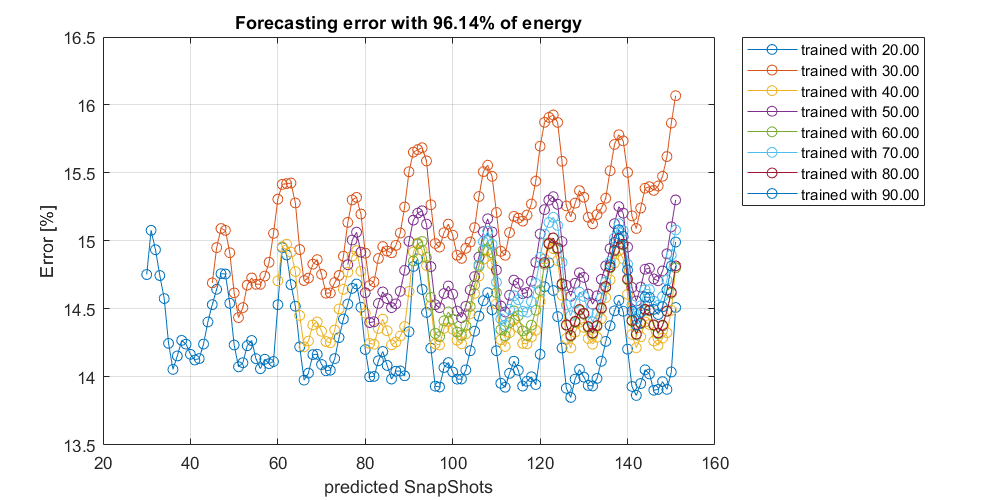

reqEnergy2 = 95.00; %In percentage
fig = fig+1;
[Phi2,omega2,lambda2, reqModes2, errorSnap2, energy2] = errorCycle(trainingPercent, reqEnergy2, XComplete, dt, time, fig);

[errorTrainMatrix, errorTestMatrix, ~] = errorSnapMatrix(trainingPercent, XComplete, dt, time, reqModes);
[errorTrainMatrix1, errorTestMatrix1, ~] = errorSnapMatrix(trainingPercent, XComplete, dt, time, reqModes1);
[errorTrainMatrix2, errorTestMatrix2, ~] = errorSnapMatrix(trainingPercent, XComplete, dt, time, reqModes2);

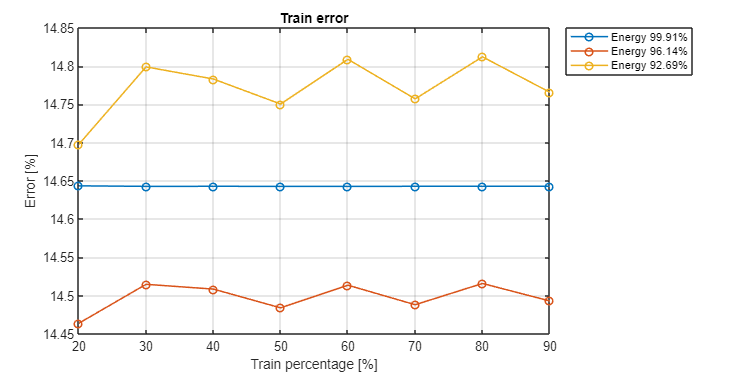

fig = fig+1;
figure(fig);
infoLeg = sprintf('Energy %.2f%%', energy);
infoLeg1 = sprintf('Energy %.2f%%', energy1);
infoLeg2 = sprintf('Energy %.2f%%', energy2);
plot(trainingPercent'*100, errorTrainMatrix, "-o", 'DisplayName', infoLeg, "LineWidth",1.2);
hold on
plot(trainingPercent'*100, errorTrainMatrix2, "-o", 'DisplayName', infoLeg2, "LineWidth",1.2);
plot(trainingPercent'*100, errorTrainMatrix1, "-o", 'DisplayName', infoLeg1, "LineWidth",1.2);
xlabel("Train percentage [%]")
ylabel("Error [%]")
title("Train error")
set(gcf,'position',[0,0,800,400])
grid on
legend('Location','bestoutside', 'NumColumns',1)
hold off

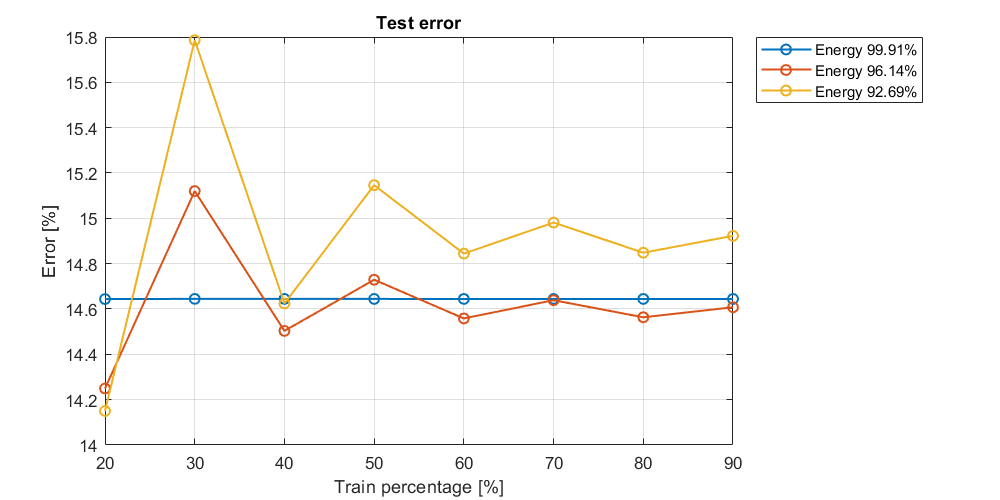

fig = fig+1;
figure(fig);
plot(trainingPercent'*100, errorTestMatrix, "-o", 'DisplayName', infoLeg, "LineWidth",1.2);
hold on
plot(trainingPercent'*100, errorTestMatrix2, "-o", 'DisplayName', infoLeg2, "LineWidth",1.2);
plot(trainingPercent'*100, errorTestMatrix1, "-o", 'DisplayName', infoLeg1, "LineWidth",1.2);
xlabel("Train percentage [%]")
ylabel("Error [%]")
title("Test error")
set(gcf,'position',[0,0,800,400])
grid on
legend('Location','bestoutside', 'NumColumns',1)
hold off

Por lo tanto,  para predicción se trabaja con 20% de datos de entrenamiento y 92.00% de energía.

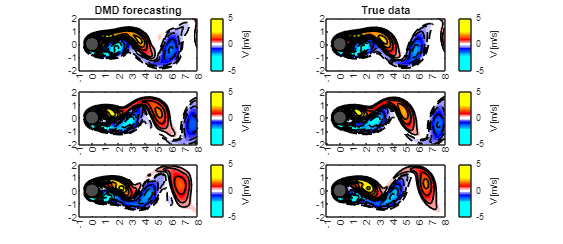

%Graph
nx = 199;
ny = 449;
[errorTrainMatrix, errorTestMatrix, Xdmd, ~] = errorSnapMatrix(0.2, XComplete, dt, time, 7);

fig = fig +1;
figure(fig)
simIndex = [40, 80, 120]; %Index
index = [1, 3, 5];
for i=1:length(simIndex)
    prueba1 = reshape(Xdmd(:,simIndex(i)),nx,ny);
    subplot(3, 2, index(i))
    plotVortex(real(prueba1));
    true01 =  reshape(XComplete(:,simIndex(i)),nx,ny);
    subplot(3, 2, index(i)+1)
    plotVortex(real(true01));
end
subplot(3,2,1)
title('DMD forecasting')  
subplot(3,2,2)
title('True data')  

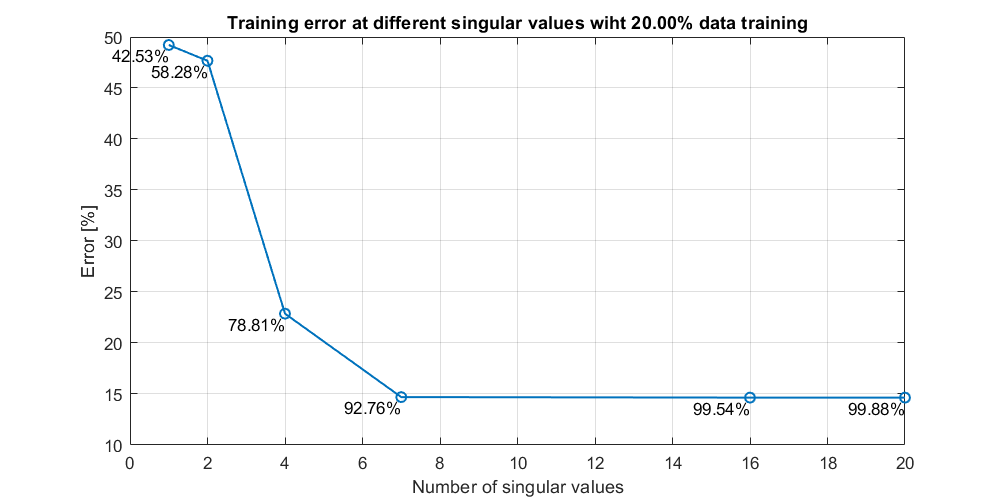

training = 0.2;
energyModes = [1, 2, 4, 7, 16, 20]';
error = zeros(length(energyModes),2);
labels = cell(1, length(energyModes));


for i = 1:length(energyModes)
    [errorTrainMatrix, errorTestMatrix, Xdmd, S] = errorSnapMatrix(training, XComplete, dt, time, energyModes(i));
    error(i,1) = errorTrainMatrix;
    error(i,2) = errorTestMatrix;

    totalEnergy = sum(diag(S));
    Sred = S(1:energyModes(i), 1:energyModes(i));
    sDiagonal = diag(Sred);           %Construyo un vector con la diagonal de S
    reduction = sum(sDiagonal);           %Sumo el vector y guardo el valor
    labels{i} = sprintf('%.2f%%', reduction/totalEnergy*100);
    
end

infoTitle = sprintf('Training error at different singular values wiht %.2f%% data training', training*100);
fig = fig + 1;
figure(fig);
plot(energyModes, error(:,1), "-o", "LineWidth",1.2);
text(energyModes, error(:,1),labels,'VerticalAlignment','top','HorizontalAlignment','right')
grid on 
xlabel("Number of singular values")
ylabel("Error [%]")
title(infoTitle)

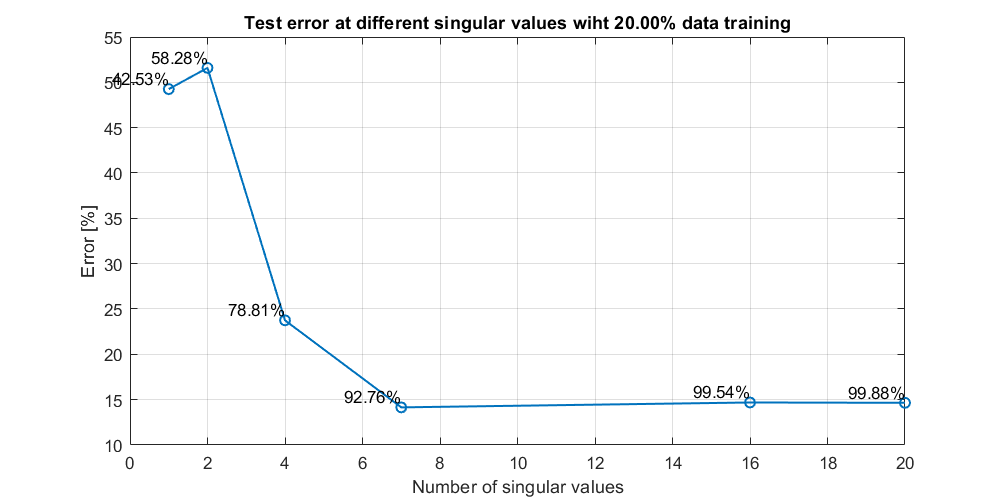

infoTitle = sprintf('Test error at different singular values wiht %.2f%% data training', training*100);
fig = fig + 1;
figure(fig);
plot(energyModes, error(:,2), "-o", "LineWidth",1.2);
text(energyModes, error(:,2),labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
grid on 
xlabel("Number of singular values")
ylabel("Error [%]")
title(infoTitle)

[errorTrainMatrix, errorTestMatrix, Xdmd, S] = errorSnapMatrix(0.2, XComplete, dt, time, 7);
indexX = [50, 100, 150];
indexY = 50;
errorProbes = zeros(150, 3);
realVortex = zeros(150, 3);
forecastingVortex = zeros(150, 3);

fig = fig +1;
figure(fig);
for j = 1:length(indexX)
    for i= 1:150
        A = reshape(XComplete(:,i), nx,ny);
        B = reshape(Xdmd(:, i), nx,ny);
        errorProbes(i, j) = norm(A(indexY, indexX(j)) - B(indexY, indexX(j)), "fro")/norm(A(indexY, indexX(j)), "fro")*100;
        realVortex(i, j) = A(indexY, indexX(j));
        forecastingVortex(i, j) = B(indexY, indexX(j));
    end
end

fig = fig + 1;
figure(fig);
index = [1, 3, 5];
snapShotIndex = [1:1:150]'; 
for i = 1:3
    subplot(3, 2, index(i))
    plot(snapShotIndex, errorProbes(:, i));
    title(sprintf("Probe at %d*D", i))
    xlabel("snapShot Index")
    ylabel("Error [%]")

    subplot(3, 2, index(i)+1)
    plot(snapShotIndex, realVortex(:, i), "DisplayName","Real vortex");
    hold on
    grid on
    title(sprintf("Probe at %d*D", i))
    xlabel("snapShot Index")
    ylabel("Vorticity [1/s]")
    plot(snapShotIndex, forecastingVortex(:, i), "DisplayName","DMD vortex");
    legend('Location','bestoutside', 'NumColumns',1)
    hold off
end
sgtitle("Comparison of vorticity at 1D, 2D and 3D with 20.00%% training data")

function  plotVortex(Vortex)
    load CCcool.mat
    %f1 = figure;
    vortmin = -5;
    vortmax = 5;

    Vortex(Vortex>vortmax) = vortmax;
    Vortex(Vortex<vortmin) = vortmin;

    imagesc(Vortex);
    colormap(CC);

    xticks([1 50 100 150 200 250 300 350 400 449])
    xticklabels({'-1','0','1','2','3','4','5','6','7','8'})
    yticks([1 50 100 150 199])
    yticklabels({'2','1','0','-1','-2'})
    set(gcf,'Position',[500 300 600 260])
    axis equal
    hold on

    contour(Vortex , [vortmin-0.5:0.5:-0.5 -0.250 -0.125], "--k", "LineWidth",1.4)
    contour(Vortex , [0.250 0.5:0.5:vortmax], "-k", "LineWidth",1.4)
    cb = colorbar;
    ylabel(cb,'V [m/s]');

    theta = [0:0.1:359.9]';
    x = ones(size(theta,2));
    y = ones(size(theta,2));
    x = 49+25*sind(theta);  %Son esos centro porque la imagen está escalada
    y = 99+25*cosd(theta);
    fill(x,y,[.3 .3 .3])  % place cylinder
    plot(x,y,'k','LineWidth',1.2) % cylinder boundary
    hold off
end

function plotCycle

end

function [errorTrainMatrix, errorTestMatrix, Xdmd, S] = errorSnapMatrix(trainingPercent, XComplete, dt, time, reqModes)
    tiTrain = 0;
    tiIndex = tiTrain/dt + 1;
    tfTrain = zeros(length(trainingPercent), 1);
    tfIndex = zeros(length(trainingPercent), 1);
    errorTrainMatrix = zeros(length(trainingPercent), 1);
    errorTestMatrix = zeros(length(trainingPercent), 1);
    
    for i = 1:length(trainingPercent)
        tfTrain(i) = round(trainingPercent(i)*151)*dt;
        tfIndex(i) =  round(trainingPercent(i)*151);
    
        %Training set
        X1 = XComplete(:,tiIndex:tfIndex(i)-1);
        X2 = XComplete(:,tiIndex+1:tfIndex(i));
    
        %How many modes do I need?
        r = reqModes(i);
        %Number of modes
        [~,~,~,~,Xdmd, S] = DMD(X1,X2,r,time,dt);
        %Compute error for training set
        errorTrainMatrix(i, 1) = norm(XComplete(:,1:tfIndex)-Xdmd(:,1:tfIndex), "fro")/norm(XComplete(:,1:tfIndex), "fro")*100;
        errorTestMatrix(i, 1) = norm(XComplete(:,tfIndex+1:end)-Xdmd(:,tfIndex+1:end), "fro")/norm(XComplete(:,tfIndex+1:end), "fro")*100;
        %Compute error for test set
    end
end


function [Phi,omega,lambda, reqModes, errorSnap, energy] = errorCycle(trainingPercent, reqEnergy, XComplete, dt, time, fig)
    tiTrain = 0;
    tiIndex = tiTrain/dt + 1;
    tfTrain = zeros(length(trainingPercent), 1);
    tfIndex = zeros(length(trainingPercent), 1);
    reqModes = zeros(length(trainingPercent), 1);
    errorSnap = zeros(151-round(trainingPercent(1)*151)+1, length(trainingPercent));
    
    for i = 1:length(trainingPercent)
        tfTrain(i) = round(trainingPercent(i)*151)*dt;
        tfIndex(i) =  round(trainingPercent(i)*151);
    
        %Training set
        X1 = XComplete(:,tiIndex:tfIndex(i)-1);
        X2 = XComplete(:,tiIndex+1:tfIndex(i));
    
        %How many modes do I need?
        [r, energy] = requiredModes(X1,reqEnergy);
        reqModes(i) = r;
        %Number of modes
        [Phi,omega,lambda,~,Xdmd,~] = DMD(X1,X2,r,time,dt);
        %Compute error
        errorSnap(1:151-tfIndex(i)+1, i) = computeErrorSnap(XComplete, Xdmd, tfIndex(i));
    end

    figure(fig);
    
    for i=1:length(tfIndex)
        snapShots = [tfIndex(i):1:151]';
        infoLeg = sprintf('trained with %.2f', trainingPercent(i)*100);
        plot(snapShots, errorSnap(1:length(snapShots),i), "-o", 'DisplayName', infoLeg);
        hold on
    end
    infoTitle = sprintf("Forecasting error with %.2f%% of energy", energy);
    xlabel("predicted SnapShots")
    ylabel("Error [%]")
    title(infoTitle)
    set(gcf,'position',[0,0,800,400])
    grid on
    legend('Location','bestoutside', 'NumColumns',1)
    hold off
end

function [r, energy] = requiredModes(X1,reqEnergy)
    %Número de modos
    r = 29;
    [~, S, ~] = svd(X1, "econ");

    Sred = S(1:r, 1:r);
    sDiagonal = diag(Sred);           %Construyo un vector con la diagonal de S
    sSuma = sum(sDiagonal);           %Sumo el vector y guardo el valor

    for i=1:r
        sSumatoria = sum(sDiagonal(1:i));%Suma acumulativa
        energy = sSumatoria/sSuma*100;
        if energy >= reqEnergy
            break
        end
    end
    r = i;
end

function error = computeErrorSnap(XComplete, Xdmd, tfIndex)
    error = zeros(151-tfIndex+1, 1);
    for i = tfIndex:151
        error(i-tfIndex+1) = norm(XComplete(:,i)-Xdmd(:,i), "fro")/norm(XComplete(:,i), "fro")*100;
    end
end

function [Phi,omega,lambda,b,Xdmd,S] = DMD(X1,X2,r,t,dt)

    [U, S, V] = svd(X1, "econ");

    Ured = U(:, 1:r); 
    Sred = S(1:r, 1:r);
    Vred = V(:, 1:r);

    Atilde = Ured'*X2*Vred*inv(Sred); % low -rank dynamics

    [Wred , D] = eig(Atilde);
    Phi = X2*Vred*inv(Sred)*Wred;

    lambda = diag(D); % discrete -time eigenvalues
    omega = log(lambda)/dt; % continuous -time eigenvalues

    %% Compute DMD mode amplitudes b
    x0 = X1(:, 1); %Condición inicial
    b = Phi\x0;

    %% DMD reconstruction
    mm1 = size(X1, 2); % mm1 = m - 1
    time_dynamics = zeros(r, mm1);

    for iter = 1:151 
        time_dynamics(:,iter) = (b.*exp(omega*t(iter)));
    end
    Xdmd = Phi*time_dynamics;
    Xdmd = real(Xdmd);
    
end


function [] = modes(r, U, alpha, t_index, nx, ny)
    numb = size(r,2);
    for i=1:numb
        figure(4+i);
        U_red = U(:,r(i));
        alpha_red = alpha(r(i),t_index);
        Avort_red = U_red*alpha_red;
        plotVortex(reshape(Avort_red,nx,ny));
        title(sprintf("Modo %d",r(i)))
    end
end